% Load data
data = readtable('/Users/shiva/Downloads/MLR-RR/enhanced_metrics.csv');
X = table(data.avg_cpu_percent, data.num_processes, data.io_bytes_sec,...
          data.context_switches_sec, data.memory_percent,...
          'VariableNames', {'CPU','Processes','IO_Bytes','Context_Switches','Memory'});
y = data.suggested_TQ_ms;

% 1. Normalize Features (Z-score)
X_normalized = normalize(X);

% 2. Train Regularized Model (Lasso)
[B, FitInfo] = lasso(X_normalized{:,:}, y, 'CV', 10);
best_idx = FitInfo.Index1SE;
coefs = [FitInfo.Intercept(best_idx); B(:,best_idx)];

% 3. Create Interpretable Model
mdl_kept = fitlm(X_normalized, y, 'linear');
disp(mdl_kept);


Linear regression model:
    y ~ 1 + CPU + Processes + IO_Bytes + Context_Switches + Memory

Estimated Coefficients:
                        Estimate       SE        tStat      pValue  
                        ________    ________    _______    _________

    (Intercept)           5.5246    0.095888     57.615    5.323e-84
    CPU                    2.137     0.09989     21.393    5.338e-41
    Processes            0.34972     0.19856     1.7613     0.080967
    IO_Bytes            -0.13809    0.097774    -1.4124      0.16066
    Context_Switches    -0.15494    0.097706    -1.5857      0.11567
    Memory              -0.36677     0.19623    -1.8691     0.064267


Number of observations: 116, Error degrees of freedom: 110
Root Mean Squared Error: 1.03


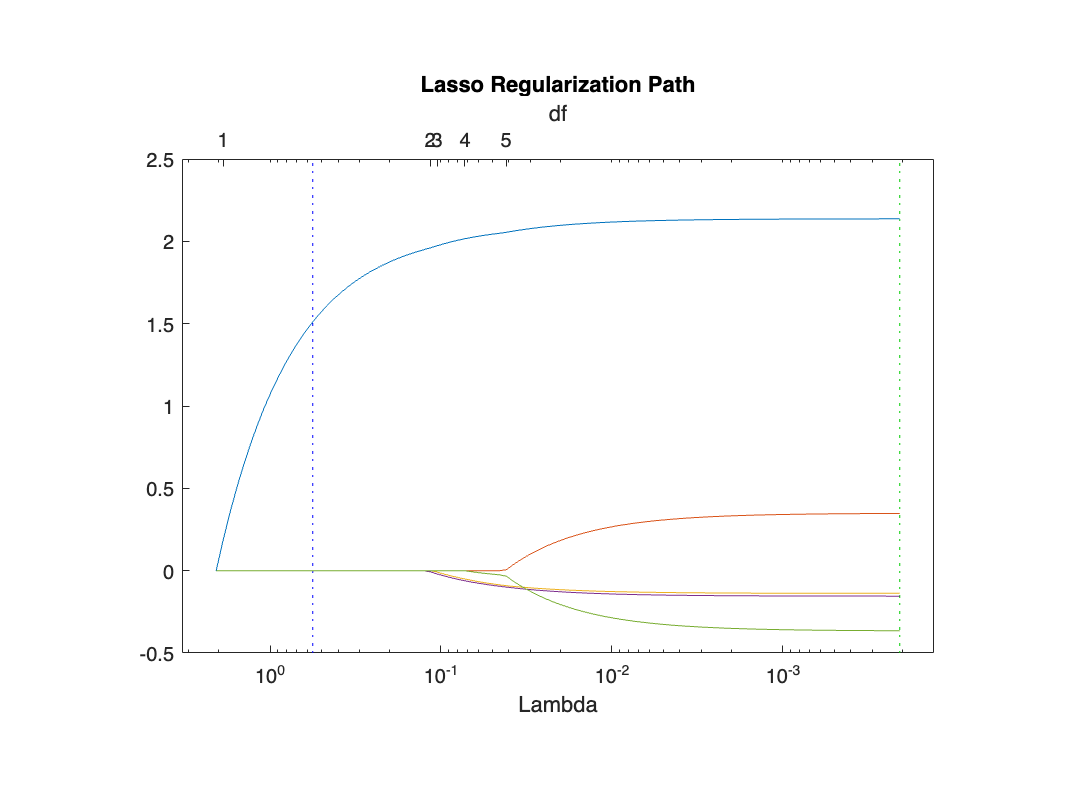


% 4. Visualize Regularization Path
figure;
lassoPlot(B, FitInfo, 'PlotType', 'Lambda', 'XScale', 'log');
title('Lasso Regularization Path');


% 5. Save Final Model
save('full_model.mat', 'mdl_kept');